**Step 0**: Preprocesseing

clearvars
clc
%run_preprocessing

Start logging to this file

diary('out/models/log.txt'); 
diary on;

**Step 1**: Load Preprocessed Data (if already done before)

global R_train test_u test_i MAXOBJ
load('out/train.mat');   % R_train, train_u, train_i, train_ctx
load('out/val.mat');     % val_u, val_i, val_ctx
load('out/test.mat');    % test_u, test_i, test_ctx

**Step 2**: Train Implicit MF through different variables

and

**Step 3: **Evaluation (Recall@20, NDCG@20)

MAXOBJ = 30;
fprintf('[%s]Run Started\n',string(datetime('now')))

[04-Sep-2025 18:44:14]Run Started


[04-Sep-2025 18:44:14][1/30] dims=24, lambda=0.8393, alpha=19, iter=6 
 Loading precomputed user/item indices...
[04-Sep-2025 18:45:45] Iter 1/6 done. time: 87.82s
[04-Sep-2025 18:47:06] Iter 2/6 done. time: 79.72s
[04-Sep-2025 18:48:25] Iter 3/6 done. time: 79.40s
[04-Sep-2025 18:49:45] Iter 4/6 done. time: 79.97s
[04-Sep-2025 18:51:05] Iter 5/6 done. time: 79.69s
[04-Sep-2025 18:52:24] Iter 6/6 done. time: 79.55s
[04-Sep-2025 19:11:10][1/30] dims=24, lambda=0.8393, alpha=19, iter=6 → Recall@20=0.9039, NDCG@20=0.6485
|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |         dims |       lambda |        alpha |         iter |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |              |
|=========================================================================

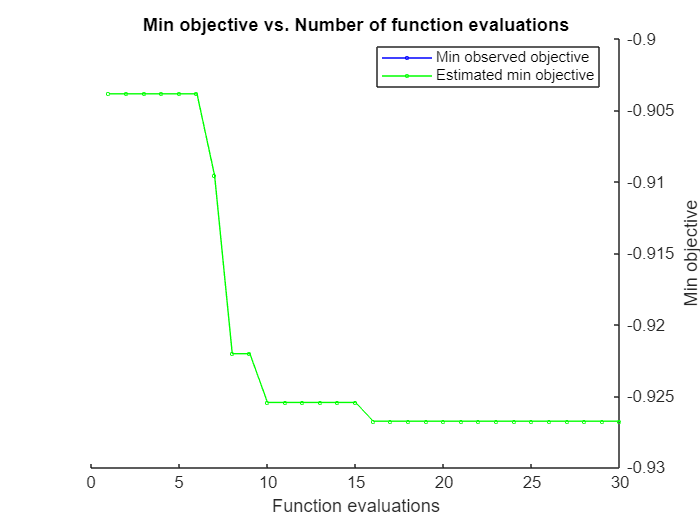


vars = [
    optimizableVariable('dims', [20, 100], 'Type', 'integer')
    optimizableVariable('lambda', [0.01, 1])
    optimizableVariable('alpha', [10, 100], 'Type', 'integer')
    optimizableVariable('iter', [5, 10], 'Type', 'integer')
];

if ~isfolder('out/models')
    mkdir('out/models');
end

resultsBO = bayesopt(@objectiveFunction, ...
    vars, ...
    'MaxObjectiveEvaluations', MAXOBJ, ...
    'IsObjectiveDeterministic', true, ...
    'Verbose', 1);


diary off;

**Step 4 (Extra) : **Saving data for benchmarking

load('out\models\results.mat')
headers = {'dims','lambda','alpha','iterations','recall20','ndcg20'};
fid = fopen('out/hyperparam_results.csv', 'w');
fprintf(fid, '%s,%s,%s,%s,%s,%s\n', headers{:});
for i = 1:size(results,1)
    fprintf(fid, '%d,%.4f,%d,%d,%.4f,%.4f\n', results(i,:));
end
fclose(fid);

**objective function : **which is created to optimize the best output

function score = objectiveFunction(x)

Global and Persistent variables for tracking and saving

    global R_train test_u test_i MAXOBJ
    persistent row_idx count result
    if isempty(row_idx)
        row_idx = 1;
        count = 0;
        result =zeros(MAXOBJ,6);
    end

   Extract hyperparameters from input struct

    k = x.dims;
    lambda = x.lambda;
    alpha = x.alpha;
    iter = x.iter;
    fprintf('[%s][%d/%d] dims=%d, lambda=%.4f, alpha=%d, iter=%d \n ', ...
    string(datetime('now')),row_idx,MAXOBJ, k, lambda, alpha, iter);

   Training

    [U, V] = implicit_mf(R_train, k, lambda, alpha, iter);


   Evaluation

    [recall20, ndcg20] = evaluate(U, V, test_u, test_i, R_train);


   Logging results

    results(row_idx, :) = [k, lambda, alpha, iter, recall20, ndcg20];
    count = count + 1;


    Progress printout

    save(fullfile('out/models', 'results.mat'), 'results', '-v7');        
    fprintf('[%s][%d/%d] dims=%d, lambda=%.4f, alpha=%d, iter=%d → Recall@20=%.4f, NDCG@20=%.4f\n', ...
    string(datetime('now')),row_idx,MAXOBJ, k, lambda, alpha, iter, recall20, ndcg20);
    drawnow;

   Save model

    model_name = sprintf('model%d_dims%d_lambda%.2f_alpha%d_iter%d.mat', row_idx, k, lambda, alpha, iter);
    save(fullfile('out/models', model_name), 'U', 'V');

   Increment row index

    row_idx = row_idx + 1;

Return negative Recall@20 for minimization

    score = -recall20;
end